%% =========================================================================
%  Dispersion analysis of a cable with metamaterial resonators
%  Author: M.RM Machado
%  =========================================================================
clc
clear all
close all

%% =========================================================================
%  CABLE GEOMETRY AND MATERIAL PROPERTIES
%  =========================================================================
L = 51.95 / 100;                % [m] Length of the cable

E = 203e9;                      % [Pa] Young's modulus
eta = 0.008;                    % Structural damping factor
im = sqrt(-1);                  % Imaginary unit
E = E * (1 + im * eta);         % Complex Young's modulus with damping

rho = 3000;                     % [kg/m^3] Density
mass = 1.3027;                  % [kg] Mass per unit length
A = pi * (0.02515 / 2)^2;       % [m^2] Cross-sectional area
Iz = A^2 / (4 * pi);            % [m^4] Area moment of inertia
T = 1.680e4;                    % [N] Tensile load

%% =========================================================================
%  WAVENUMBER CALCULATION - BARE CABLE
%  =========================================================================
freq = 0.001:0.01:20;           % Frequency range [Hz]
w = 2 * pi * freq;              % Angular frequency [rad/s]

for ii = 1:length(w)
    % Wavenumber for Euler-Bernoulli beam with axial load
    knb(ii) = (rho * A * w(ii)^2 / (E * Iz))^(1/4);
    
    % Group velocity calculations
    gvb(ii) = 2 * w(ii) / knb(ii);
    gvb2(ii) = 2 * sqrt(w(ii)) * (E * Iz / (rho * A))^(1/4);
end

% Plot wavenumber
figure;
plot(freq, knb)

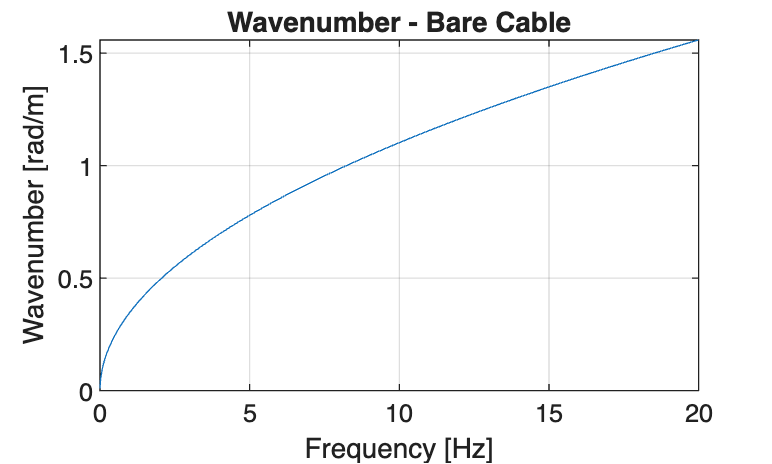

xlabel('Frequency [Hz]');
ylabel('Wavenumber [rad/m]');
title('Wavenumber - Bare Cable');
grid on;

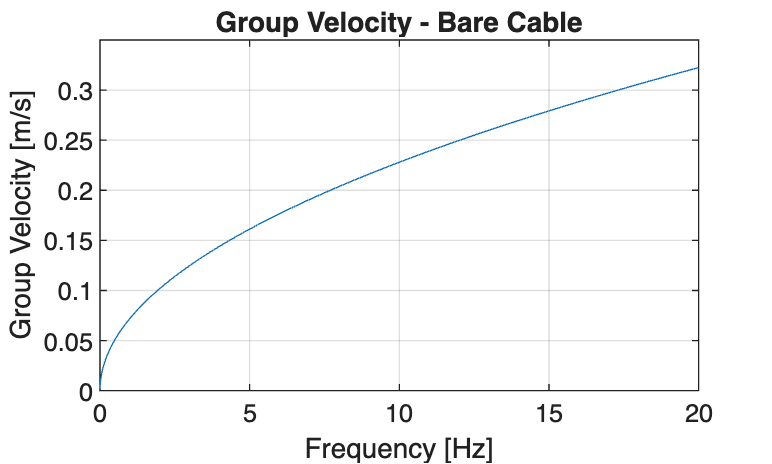


% Plot group velocity
figure;
plot(freq, imag(gvb2))
xlabel('Frequency [Hz]');
ylabel('Group Velocity [m/s]');
title('Group Velocity - Bare Cable');
grid on;

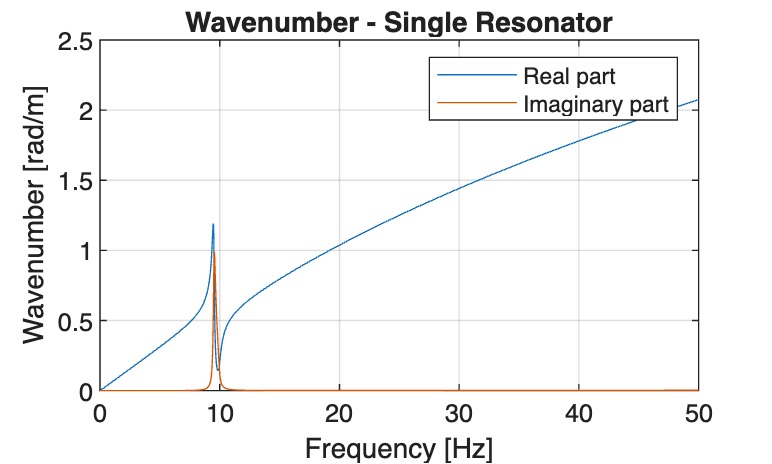


%% =========================================================================
%  RESONATOR CONFIGURATION
%  =========================================================================
mu = rho * A * L;               % Total mass of the structure [kg]
mp = mu * 0.1;                  % Total mass of all resonators [kg]
S = L / 10;                     % Number of resonators

%% =========================================================================
%  CASE 1: SINGLE RESONATOR
%  =========================================================================
res_type = 1;                   % 1: single, 2: multiple, 3: graded

% Single resonator properties
wp = 9.514 * pi * 2;            % Resonator natural frequency [rad/s]
m_ration = 0.003;               % Mass ratio
mtot_res = m_ration * (rho * A * L); % Total resonator mass [kg]
numb_res = 10;                  % Number of resonators
mr = mtot_res / numb_res;       % Mass of each resonator [kg]
fr = 9.514;                     % Resonator natural frequency [Hz]
kr = mr * (2 * pi * fr)^2;      % Dynamic stiffness of resonator [N/m]
kr = kr * (1 + 1i * eta);       % With damping

% Frequency range for dispersion analysis
freq = 0.001:0.01:50;           % Frequency range [Hz]
w = 2 * pi * freq;              % Angular frequency [rad/s]
wp = 2 * pi * 9.51;             % Resonator angular frequency [rad/s]
kappa = T / (E * Iz) / 2;       % Axial load parameter
eps = 0.1;                      % Coupling parameter

for ii = 1:length(w)
    % Resonator response function
    resp = 1 + 0.1 * (1 / (1 - (w(ii) / (wp * (1 + 1i * 0.008)))^2));
    
    % Wavenumber with single resonator
    knc(ii) = sqrt(-kappa * resp + sqrt(kappa^2 + rho * A * w(ii)^2 / (E * Iz)) * resp);
    
    % Group velocity with resonator
    gv(ii) = 2 * (w(ii) / knc(ii));
end

% Plot wavenumber (real and imaginary parts)
figure;
plot(freq, real(knc), freq, -imag(knc))
xlabel('Frequency [Hz]');
ylabel('Wavenumber [rad/m]');
title('Wavenumber - Single Resonator');
legend('Real part', 'Imaginary part');
grid on;


% Plot group velocity
figure;
plot(freq, gv)

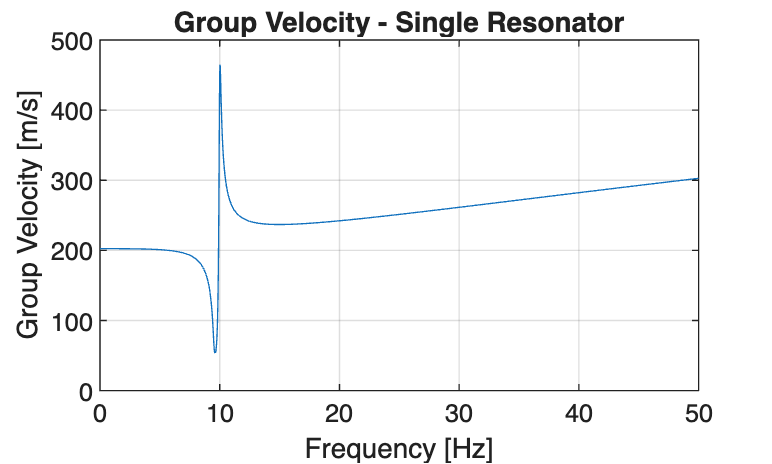

xlabel('Frequency [Hz]');
ylabel('Group Velocity [m/s]');
title('Group Velocity - Single Resonator');
grid on;

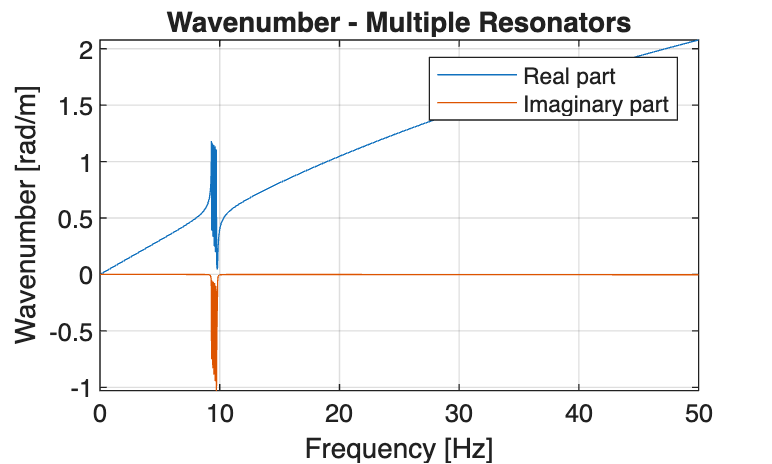


%% =========================================================================
%  CASE 2: MULTIPLE RESONATORS
%  =========================================================================
m_ration2 = 1e-3;               % Mass ratio for multiple resonators
mtot_res2 = m_ration2 * (rho * A * L); % Total resonator mass [kg]
mrm = mtot_res2 / numb_res;     % Mass of each resonator [kg]

% Define 5 resonators with different frequencies (detuned)
wp2 = (9.514 - 0.1) * pi * 2 * (1 + 1i * 0.0008);
kr2 = mrm * (wp2)^2;
kr2 = kr2 * (1 + 1i * eta);

wp3 = (9.514 - 0.2) * pi * 2 * (1 + 1i * 0.0008);
kr3 = mrm * (wp3)^2;
kr3 = kr3 * (1 + 1i * eta);

wp1 = (9.514) * pi * 2 * (1 + 1i * 0.0008);
kr1 = mrm * (wp1)^2;
kr1 = kr1 * (1 + 1i * eta);

wp4 = (9.514 + 0.1) * pi * 2 * (1 + 1i * 0.0008);
kr4 = mrm * (wp4)^2;
kr4 = kr4 * (1 + 1i * eta);

wp5 = (9.514 + 0.2) * pi * 2 * (1 + 1i * 0.0008);
kr5 = mrm * (wp5)^2;
kr5 = kr5 * (1 + 1i * eta);

eps = 0.01;                     % Coupling parameter

for ii = 1:length(w)
    % Response with multiple resonators
    resp = 1 + (eps * (1 / (1 - (w(ii) / wp1)^2)) + ...
                eps * (1 / (1 - (w(ii) / wp2)^2)) + ...
                eps * (1 / (1 - (w(ii) / wp3)^2)) + ...
                eps * (1 / (1 - (w(ii) / wp4)^2)) + ...
                eps * (1 / (1 - (w(ii) / wp5)^2)));
    
    % Wavenumber with multiple resonators
    knc(ii) = sqrt(-kappa + sqrt(kappa^2 + resp * rho * A * w(ii)^2 / (E * Iz)));
end

% Plot wavenumber (real and imaginary parts)
figure;
plot(freq, real(knc), freq, imag(knc))
xlabel('Frequency [Hz]');
ylabel('Wavenumber [rad/m]');
title('Wavenumber - Multiple Resonators');
legend('Real part', 'Imaginary part');
grid on;

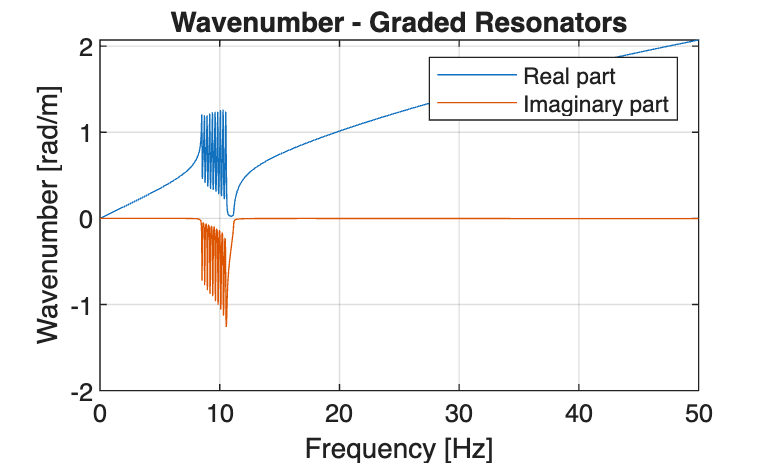


%% =========================================================================
%  CASE 3: GRADED RESONATORS
%  =========================================================================
m_rationg = 0.03;               % Mass ratio for graded resonators
wpg = 2 * pi * 9.51;            % Central frequency [rad/s]
mtot_resg = m_rationg * (rho * A * L); % Total resonator mass [kg]
delOm = 1 * pi * 2;             % Frequency span [rad/s]
Ss = 10;                        % Number of resonators

% Graded resonator frequencies (linearly distributed)
jj = 1:Ss;
wpj = wpg + delOm - 2 * delOm * ((jj - 1) ./ (Ss - 1)).^1;
wpj = wpj * (1 + 1i * 0.002);   % With damping

% Mass of each resonator
mrj = mtot_resg / Ss;
krg = mrj * wpj.^2;             % Stiffness of each resonator
krg = krg * (1 + 1i * 0.008);   % With damping

eps = 0.03;                     % Coupling parameter

for ii = 1:length(w)
    cres = 0;
    for ji = 1:length(wpj)
        % Response from each graded resonator
        cres1 = eps * 1 / (1 - (w(ii) / wpj(ji))^2);
        cres = cres + cres1;
    end
    resp = 1 + cres;
    
    % Wavenumber with graded resonators
    knc(ii) = sqrt(-kappa + sqrt(kappa^2 + resp * rho * A * w(ii)^2 / (E * Iz)));
end

% Plot wavenumber (real and imaginary parts)
figure;
plot(freq, real(knc), freq, imag(knc))
xlabel('Frequency [Hz]');
ylabel('Wavenumber [rad/m]');
title('Wavenumber - Graded Resonators');
legend('Real part', 'Imaginary part');
grid on;


disp('Analysis complete!');

Analysis complete!
